# Modelo de CD - Phantom

Juan Nicolás Carvajal Useche

Edgar Giovanny Obregón Espitia

%clear all
%Mediciones con el calibrador
B= 90; %base
L1 = 45;
L2 = 105;
L3 = 105;
L4 = 75;
T = 20;%Distancia al centro del gripper

Cinemática directa

Base = MTH(B,0,0,0)

Base =      1     0     0    90
     0     1     0     0
     0     0     1     0
     0     0     0     1


L(1) = Link('revolute', 'd' , L1 , 'a' , 0 , 'alpha' , pi/2 , 'offset' , 0 , 'qlim' , [0 2*pi] ); 
L(2) = Link('revolute', 'd' , 0 , 'a' , L2,'alpha' , 0 , 'offset' , pi/2 , 'qlim' , [0 2*pi] );     
L(3) = Link('revolute', 'd' , 0, 'a' , L3 ,'alpha' , 0 , 'offset' , 0 , 'qlim' , [0 2*pi] );     
L(4) = Link('revolute', 'd' , 0 , 'a' , L4 , 'alpha' , 0 , 'offset' , 0 , 'qlim' , [0 2*pi] );  
TC=rt2tr(rotx(90,"deg")*roty(90,"deg"),[T 0 0]')

TC =      0     0     1    20
     1     0     0     0
     0     1     0     0
     0     0     0     1



Phantom = SerialLink(L,'name','Phantom','tool',TC,'base',Base)

 
Phantom = 
 
Phantom:: 4 axis, RRRR, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         45|          0|     1.5708|          0|
|  2|         q2|          0|        105|          0|     1.5708|
|  3|         q3|          0|        105|          0|          0|
|  4|         q4|          0|         75|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (90, 0, 0), RPY/xyz = (0, 0, 0) deg                 
tool:    t = (20, 0, 0), RPY/xyz = (0, 90, 90) deg               
 



syms L1s L2s L3s L4s q1 q2 q3 q4

TB1 = Base

TB1 =      1     0     0    90
     0     1     0     0
     0     0     1     0
     0     0     0     1


T10 = MTH(0,L1s,90,q1+180)

$$T10 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\left(q_{1}+180\right)}{180}\right) & 0 & \sin\left(\frac{\pi \,\left(q_{1}+180\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,\left(q_{1}+180\right)}{180}\right) & 0 & -\cos\left(\frac{\pi \,\left(q_{1}+180\right)}{180}\right) & 0\\ 0 & 1 & 0 & \mathrm{L1s}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T21 = MTH(L2s,0,0,q2)

$$T21 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{2}}{180}\right) & -\sin\left(\frac{\pi \,q_{2}}{180}\right) & 0 & \mathrm{L2s}\,\cos\left(\frac{\pi \,q_{2}}{180}\right)\\ \sin\left(\frac{\pi \,q_{2}}{180}\right) & \cos\left(\frac{\pi \,q_{2}}{180}\right) & 0 & \mathrm{L2s}\,\sin\left(\frac{\pi \,q_{2}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T32 = MTH(L3s,0,0,q3)

$$T32 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{3}}{180}\right) & -\sin\left(\frac{\pi \,q_{3}}{180}\right) & 0 & \mathrm{L3s}\,\cos\left(\frac{\pi \,q_{3}}{180}\right)\\ \sin\left(\frac{\pi \,q_{3}}{180}\right) & \cos\left(\frac{\pi \,q_{3}}{180}\right) & 0 & \mathrm{L3s}\,\sin\left(\frac{\pi \,q_{3}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T43 = MTH(L4s,0,0,q4)

$$T43 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{4}}{180}\right) & -\sin\left(\frac{\pi \,q_{4}}{180}\right) & 0 & \mathrm{L4s}\,\cos\left(\frac{\pi \,q_{4}}{180}\right)\\ \sin\left(\frac{\pi \,q_{4}}{180}\right) & \cos\left(\frac{\pi \,q_{4}}{180}\right) & 0 & \mathrm{L4s}\,\sin\left(\frac{\pi \,q_{4}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Cinemática directa 
T40 = TB1*T10*T21*T32*T43*TC

Se calculan las poses usando la CD

T40_H = double(subs(T40,[L1s L2s L3s L4s q1 q2 q3 q4 ],[L1 L2 L3 L4 0 0 0 0]))

T40_H =      0     0    -1  -215
     0     1     0     0
     1     0     0    45
     0     0     0     1


T40_1 = double(subs(T40,[L1s L2s L3s L4s q1 q2 q3 q4 ],[L1 L2 L3 L4 25 25 20 -20]))

T40_1 =     0.3830   -0.4226   -0.8214 -141.5687
    0.1786    0.9063   -0.3830 -107.9822
    0.9063         0    0.4226  203.7699
         0         0         0    1.0000


T40_2 = double(subs(T40,[L1s L2s L3s L4s q1 q2 q3 q4 ],[L1 L2 L3 L4 -35 35 -30 30]))

T40_2 =     0.4698    0.5736   -0.6710 -129.8857
   -0.3290    0.8192    0.4698  153.9656
    0.8192         0    0.5736  168.8666
         0         0         0    1.0000


T40_3 = double(subs(T40,[L1s L2s L3s L4s q1 q2 q3 q4 ],[L1 L2 L3 L4 85 -20 55 25]))

T40_3 =     0.0755   -0.9962   -0.0436   69.7643
    0.8627    0.0872   -0.4981 -231.2952
    0.5000         0    0.8660  151.5858
         0         0         0    1.0000


T40_4 = double(subs(T40,[L1s L2s L3s L4s q1 q2 q3 q4 ],[L1 L2 L3 L4 80 -35 55 -45]))

T40_4 =    -0.0734   -0.9848   -0.1574   42.9799
   -0.4162    0.1736   -0.8925 -266.6642
    0.9063         0   -0.4226  -19.4621
         0         0         0    1.0000


Orientación en ángulos fijos

poseRPY_H = [T40_H(1:3,4);tr2rpy(T40_H,'deg')']

poseRPY_H =   -215
     0
    45
     0
   -90
     0


poseRPY_1 = [T40_1(1:3,4);tr2rpy(T40_1,'deg')']

poseRPY_1 =  -141.5687
 -107.9822
  203.7699
         0
  -65.0000
   25.0000


poseRPY_2 = [T40_2(1:3,4);tr2rpy(T40_2,'deg')']

poseRPY_2 =  -129.8857
  153.9656
  168.8666
         0
  -55.0000
  -35.0000


poseRPY_3 = [T40_3(1:3,4);tr2rpy(T40_3,'deg')']

poseRPY_3 =    69.7643
 -231.2952
  151.5858
         0
  -30.0000
   85.0000


poseRPY_4 = [T40_4(1:3,4);tr2rpy(T40_4,'deg')']

poseRPY_4 =    42.9799
 -266.6642
  -19.4621
  180.0000
  -65.0000
 -100.0000


Orientación en ángulos de euler

poseEul_H = [T40_H(1:3,4);tr2eul(T40_H,'deg')']

poseEul_H =   -215
     0
    45
   180
    90
  -180


poseEul_1 = [T40_1(1:3,4);tr2eul(T40_1,'deg')']

poseEul_1 =  -141.5687
 -107.9822
  203.7699
 -155.0000
   65.0000
  180.0000


poseEul_2 = [T40_2(1:3,4);tr2eul(T40_2,'deg')']

poseEul_2 =  -129.8857
  153.9656
  168.8666
  145.0000
   55.0000
 -180.0000


poseEul_3 = [T40_3(1:3,4);tr2eul(T40_3,'deg')']

poseEul_3 =    69.7643
 -231.2952
  151.5858
  -95.0000
   30.0000
 -180.0000


poseEul_4 = [T40_4(1:3,4);tr2eul(T40_4,'deg')']

poseEul_4 =    42.9799
 -266.6642
  -19.4621
 -100.0000
  115.0000
  180.0000


Orientaciones deseadas

Home = [0 0 0 0] ;
P1= [deg2rad(25) deg2rad(25) deg2rad(20) deg2rad(-20)];
P2= [deg2rad(-35) deg2rad(35) deg2rad(-30) deg2rad(30)];
P3= [deg2rad(85) deg2rad(-20) deg2rad(55) deg2rad(25)];
P4= [deg2rad(80) deg2rad(-35) deg2rad(55) deg2rad(-45)];

CD

Phantom.fkine(Home)

 

ans = 
        -1         0         0        90
         0        -1         0         0
         0         0         1       350
         0         0         0         1


Phantom.fkine(P1)

 

ans = 
   -0.8214    0.4226   -0.3830    -53.89
   -0.3830   -0.9063   -0.1786     -67.1
   -0.4226         0    0.9063     300.5
         0         0         0         1


Phantom.fkine(P2)

 

ans = 
   -0.6710   -0.5736   -0.4698    -11.47
    0.4698   -0.8192    0.3290     71.05
   -0.5736         0    0.8192     313.4
         0         0         0         1


Phantom.fkine(P3)

 

ans = 
   -0.0436    0.9962   -0.0755     80.71
   -0.4981   -0.0872   -0.8627    -106.2
   -0.8660         0    0.5000     277.2
         0         0         0         1


Phantom.fkine(P4)

 

ans = 
   -0.1574    0.9848    0.0734     101.2
   -0.8925   -0.1736    0.4162     63.48
    0.4226         0    0.9063     315.8
         0         0         0         1


Plots

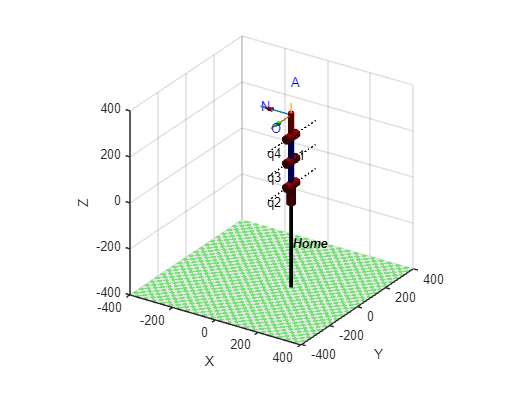

Phantom.name = 'Home';
ws = [-400 400 -400 400 -400 400];
figure()
Phantom.plot(Home,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

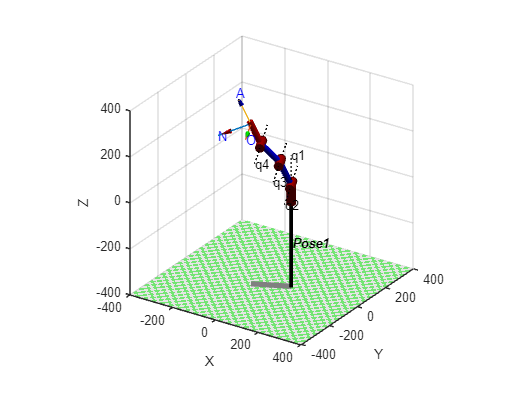


Phantom.name = 'Pose1';
ws = [-400 400 -400 400 -400 400];
figure()
Phantom.plot(P1,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

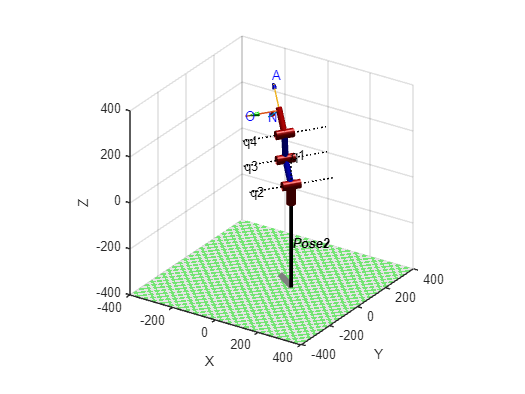


Phantom.name = 'Pose2';
ws = [-400 400 -400 400 -400 400];
figure()
Phantom.plot(P2,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

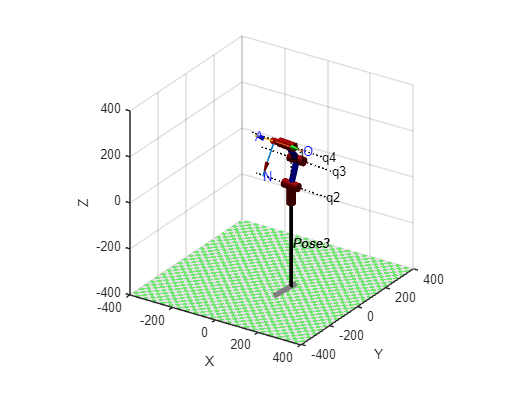


Phantom.name = 'Pose3';
ws = [-400 400 -400 400 -400 400];
figure()
Phantom.plot(P3,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

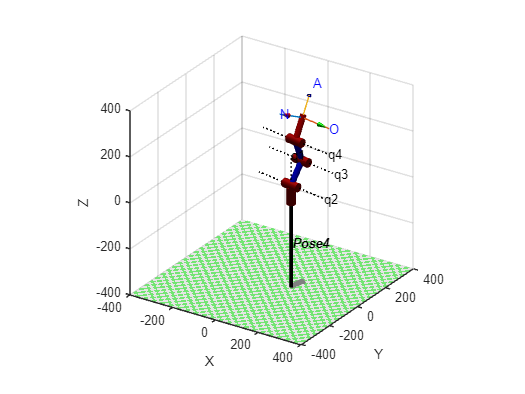


Phantom.name = 'Pose4';
ws = [-400 400 -400 400 -400 400];
figure()
Phantom.plot(P4,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

Funciones usadas

function [Res] = MTH(a,d,alpha,theta)
Res = [cosd(theta) -sind(theta)*cosd(alpha) sind(theta)*sind(alpha) a*cosd(theta); 
       sind(theta) cosd(theta)*cosd(alpha) -cosd(theta)*sind(alpha) a*sind(theta); 
       0 sind(alpha) cosd(alpha) d; 
       0 0 0 1];
end